# Thick Plate Finite Element Model

by Simone Coniglio and prof Joseph Morlier ISAE-SUPAERO

## Geometry interpolation

Gemetric description and displacement interpolation of a Quad4 finite element

Given the node coordinates:


$${\mathbf{X}}_{\mathbf{c}} =\left\lbrack \begin{array}{c}
x_1  & x_2  & x_3  & x_4 \\
y_1  & y_2  & y_3  & y_4 \\
z_1  & z_2  & z_3  & z_4 
\end{array}\right\rbrack$$


the middle plane geometry can be interpolated throught bilinear interpolation:


$$\mathbf{X}\left(s,r,t\right)=\sum_{h=1}^{4} {\mathbf{X}}_{\mathbf{ch}} N_h \left(s,r\right)+\frac{t}{2}a_h N_h \left(s,r\right){\hat{\mathbf{V}} }_{\mathbf{nh}}$$


Where the 4 bilinear shape function are:


$$N_h \left(s,r\right)=\frac{1}{4}\left(1+s_h s\right)\left(1+r_h r\right)$$


and ${\mathbf{V}}_{n\mathbf{\text{h}}}$ are the vertex normal.

To find this vector we can compute the vectors:


$${\mathbf{V}}_{s\mathbf{\text{h}}} =$$

$$\sum_{h=1}^{4} {\mathbf{X}}_{\mathbf{ch}} \frac{\partial N_h }{\partial s}\left(s_h ,r_h \right)$$
 


$${\mathbf{V}}_{\mathbf{rh}} =$$

$$\sum_{h=1}^{4} {\mathbf{X}}_{\mathbf{\text{ch}}} \frac{\partial N_h }{\partial r}\left(s_h ,r_h \right)$$


Then  ${\hat{\mathbf{V}} }_{n\mathbf{h}}$ is:


$${\hat{\mathbf{V}} }_{n\mathbf{h}} =\frac{{\mathbf{V}}_{s\mathbf{\text{h}}} \times {\mathbf{V}}_{\mathbf{rh}} }{\left\|{\mathbf{V}}_{s\mathbf{\text{h}}} \times {\mathbf{V}}_{\mathbf{rh}} \right\|}$$


## Displacement interpolation and strain-displacement matrix

The only hypothesys made for this kind of element is the fact that the thickness is rigid and the consequent stress vanishes.

The displacement will be considered as:


$$\mathbf{u}\left(s,r,t\right)=\sum_{h=1}^{4} {\mathbf{u}}_{\mathbf{h}} N_h \left(s,r\right)+\frac{t}{2}a_h N_{\theta h} \left(s,r\right)\theta_h {\times \hat{\mathbf{V}} }_{\mathbf{nh}} =\left\lbrack H\left(s,r,t\right)\right\rbrack \mathbf{q}$$


It is possible to define distinct shape functions for angles and displacements. If we consentrate on the transversal behavior:


$$w=$$

$$\sum_{h=1}^{4} w_{\mathbf{h}} N_h \left(s,r\right)$$



$$\phi =$$

$$\sum_{h=1}^{4} {\phi \text{\,}}_{\mathbf{h}} N_h \left(s,r\right)$$


where 


$$\phi =\left\lbrack \begin{array}{c}
\phi_s \\
\phi_r 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0 & 1\\
-1 & 0
\end{array}\right\rbrack$$

$$\left\lbrack \begin{array}{c}
\theta_s \\
\theta_r 
\end{array}\right\rbrack$$


Defining


$$\mathcal{L}$$

$$=\left\lbrack \begin{array}{c}
\frac{\partial }{\partial s} & 0\\
0 & \frac{\partial }{\partial r}\\
\frac{\partial }{\partial r} & \frac{\partial }{\partial s}
\end{array}\right\rbrack$$


so that we can call:


$$\varepsilon_m =$$

$$\mathcal{L}\phi=\sum_{h=1}^4\mathcal{L}N_h \phi_h=\begin{array}{cc}[0 & B_{m\phi}]\end{array}\left\lbrace\begin{array}{c}w \\ \phi\end{array}\right\rbrace$$



$$\varepsilon_m =\left\lbrack \begin{array}{c}
0 & 0 & 0 & 0 & \frac{\partial N_1 }{\partial s} & 0 & \frac{\partial N_2 }{\partial s} & 0 & \frac{\partial N_3 }{\partial s} & 0 & \frac{\partial N_4 }{\partial s} & 0\\
0 & 0 & 0 & 0 & 0 & \frac{\partial N_1 }{\partial r} & 0 & \frac{\partial N_2 }{\partial r} & 0 & \frac{\partial N_3 }{\partial r} & 0 & \frac{\partial N_4 }{\partial r}\\
0 & 0 & 0 & 0 & \frac{\partial N_1 }{\partial r} & \frac{\partial N_1 }{\partial s} & \frac{\partial N_2 }{\partial r} & \frac{\partial N_2 }{\partial s} & \frac{\partial N_3 }{\partial r} & \frac{\partial N_3 }{\partial s} & \frac{\partial N_4 }{\partial r} & \frac{\partial N_4 }{\partial s}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
w_1 \\
w_2 \\
w_3 \\
w_4 \\
\phi_{s1} \\
\phi_{r1} \\
\phi_{s2} \\
\phi_{r2} \\
\phi_{s3} \\
\phi_{r3} \\
\phi_{s4} \\
\phi_{r4} 
\end{array}\right\rbrack$$



$$\varepsilon_t =\nabla w+\phi =$$

$$\sum_{h=1}^{4} w_{\mathbf{h}} {\nabla \text{\,}N}_h \left(s,r\right)+N_h \phi_h$$

$$=\begin{array}{cc}[B_{sw} & B_{s\phi}]\end{array}\left\lbrace\begin{array}{c}w \\ \phi\end{array}\right\rbrace$$



$$\varepsilon_t =\left\lbrack \begin{array}{c}
\frac{\partial N_1 }{\partial s} & \frac{\partial N_2 }{\partial s} & \frac{\partial N_3 }{\partial s} & \frac{\partial N_4 }{\partial s} & N_1  & 0 & N_2  & 0 & N_3  & 0 & N_4  & 0\\
\frac{\partial N_1 }{\partial r} & \frac{\partial N_2 }{\partial r} & \frac{\partial N_3 }{\partial r} & \frac{\partial N_4 }{\partial r} & 0 & N_1  & 0 & N_2  & 0 & N_3  & 0 & N_4 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
w_1 \\
w_2 \\
w_3 \\
w_4 \\
\phi_{s1} \\
\phi_{\text{r1}} \\
\phi_{\text{s2}} \\
\phi_{\text{r2}} \\
\phi_{\text{s3}} \\
\phi_{\text{r3}} \\
\phi_{\text{s4}} \\
\phi_{\text{r4}} 
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
\varepsilon_s \\
\varepsilon_r \\
\varepsilon_{\text{rs}} 
\end{array}\right\rbrack =\left\lbrack B_{uv} \right\rbrack \left\lbrace q_{uv} \right\rbrace =\left\lbrack \begin{array}{c}
\frac{\partial N_1 }{\partial s} & 0 & \frac{\partial N_2 }{\partial s} & 0 & \frac{\partial N_3 }{\partial s} & 0 & \frac{\partial N_4 }{\partial s} & 0\\
0 & \frac{\partial N_1 }{\partial r} & 0 & \frac{\partial N_2 }{\partial r} & 0 & \frac{\partial N_3 }{\partial r} & 0 & \frac{\partial N_4 }{\partial r}\\
\frac{\partial N_1 }{\partial r} & \frac{\partial N_1 }{\partial s} & \frac{\partial N_2 }{\partial r} & \frac{\partial N_2 }{\partial s} & \frac{\partial N_3 }{\partial r} & \frac{\partial N_3 }{\partial s} & \frac{\partial N_4 }{\partial r} & \frac{\partial N_4 }{\partial s}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \\
v_1 \\
u_2 \\
v_2 \\
u_3 \\
v_3 \\
u_4 \\
v_4 
\end{array}\right\rbrack$$


## Momentum/Shear - deformation relations

Defining the material property:


$$D=\frac{{Et}^3 }{12\left(1-\nu^2 \right)}$$


then one can compute the moments vector as:


$$\mathbf{M}=\left\lbrack \begin{array}{c}
M_s \\
M_r \\
M_{sr} 
\end{array}\right\rbrack =D\left\lbrack \begin{array}{c}
1 & \nu  & 0\\
\nu  & 1 & 0\\
0 & 0 & \frac{\left(1-\nu \text{\,}\right)}{2}
\end{array}\right\rbrack \varepsilon_m$$


and the shear forces as:


$$\mathbf{T}=\left\lbrack \begin{array}{c}
T_s \\
T_r 
\end{array}\right\rbrack =\kappa \text{Gt}\left\lbrack \begin{array}{c}
1 & 0\\
0 & 1
\end{array}\right\rbrack \varepsilon_t$$


for the membrane behavior:


$$\sigma =\left\lbrack \begin{array}{c}
\sigma_s \\
\sigma_r \\
\sigma_{rs} 
\end{array}\right\rbrack =\frac{E}{1-\nu^2 }$$

$$\left\lbrack \begin{array}{c}
1 & \nu  & 0\\
\nu  & 1 & 0\\
0 & 0 & \frac{\left(1-\nu \text{\,}\right)}{2}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\varepsilon_s \\
\varepsilon_r \\
\varepsilon_{rs} 
\end{array}\right\rbrack$$


## Local/global displacements

First of all we will use the several convention for the local DOFs:


$$\left\lbrace q\right\rbrace ={\left\lbrace q_1 ,q_2 ,q_3 ,q_4 \right\rbrace }^T$$


where


$$q_e =\left\lbrace u_e ,v_e ,w_e ,\phi_{se} ,\phi_{re} ,\phi_{te} \right\rbrace$$


the Global DOF vector can be expressed as:


$${\tilde{q} }_e =\left\lbrace u_{xe} ,v_{ye} ,w_{ze} ,\phi_{x\text{e}} ,\phi_{y\text{e}} ,\phi_{z\text{e}} \right\rbrace$$



$${\left\lbrace q_e \right\rbrace }^T$$

$$=$$

$${\left\lbrack T_e \right\rbrack }_{\text{l}g} {\left\lbrace \tilde{q_e } \right\rbrace }^T$$


## Stiffness Matrix


$$\left\lbrack K\right\rbrack =\int {{\left\lbrack T\right\rbrack }^T \left\lbrack B\right\rbrack }^T \left\lbrack D\right\rbrack \left\lbrack B\right\rbrack \left\lbrack T\right\rbrack d\Omega \text{\,}$$


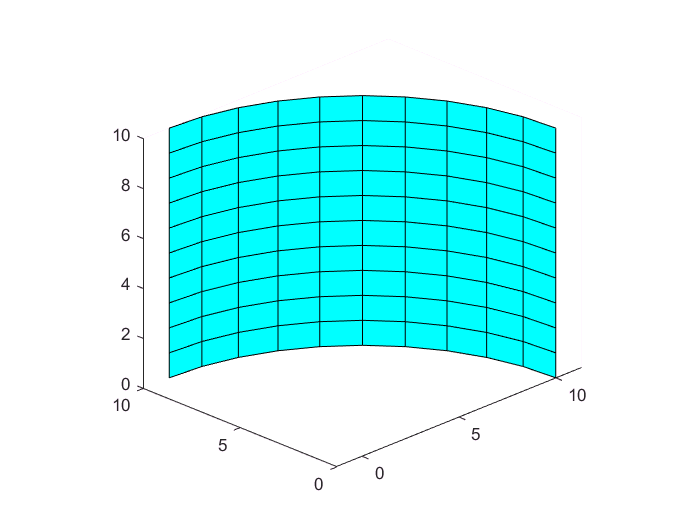

nx=10;
ny=10;
nu=0.3;
t=1;
E=1;
R=10;
theta=linspace(0,pi/2,nx+1);
zeta=linspace(0,10,ny+1);
[Tet,Z]=meshgrid(theta,zeta);
COORD=[R*cos(Tet(:)');
    R*sin(Tet(:)');
    Z(:)']';
nodenrs=reshape(1:((nx+1)*(ny+1)),ny+1,nx+1);
ELEMENT=zeros(nx*ny,4);
elid=0;
for k=1:ny
    for l=1:nx
        elid=elid+1;
        ELEMENT(elid,:)=[nodenrs(k,l) nodenrs(k+1,l) nodenrs(k+1,l+1) nodenrs(k,l+1)];
    end
end
ELEMENT_DOF=[6*(ELEMENT(:,1)-1)+1,6*(ELEMENT(:,1)-1)+2,6*(ELEMENT(:,1)-1)+3,6*(ELEMENT(:,1)-1)+4,6*(ELEMENT(:,1)-1)+5,6*(ELEMENT(:,1)-1)+6];
ELEMENT_DOF=[ELEMENT_DOF,6*(ELEMENT(:,2)-1)+1,6*(ELEMENT(:,2)-1)+2,6*(ELEMENT(:,2)-1)+3,6*(ELEMENT(:,2)-1)+4,6*(ELEMENT(:,2)-1)+5,6*(ELEMENT(:,2)-1)+6];
ELEMENT_DOF=[ELEMENT_DOF,6*(ELEMENT(:,3)-1)+1,6*(ELEMENT(:,3)-1)+2,6*(ELEMENT(:,3)-1)+3,6*(ELEMENT(:,3)-1)+4,6*(ELEMENT(:,3)-1)+5,6*(ELEMENT(:,3)-1)+6];
ELEMENT_DOF=[ELEMENT_DOF,6*(ELEMENT(:,4)-1)+1,6*(ELEMENT(:,4)-1)+2,6*(ELEMENT(:,4)-1)+3,6*(ELEMENT(:,4)-1)+4,6*(ELEMENT(:,4)-1)+5,6*(ELEMENT(:,4)-1)+6];
figure
patch('Faces',ELEMENT,'Vertices',COORD,'FaceColor','c')
axis equal
view(-45,24)

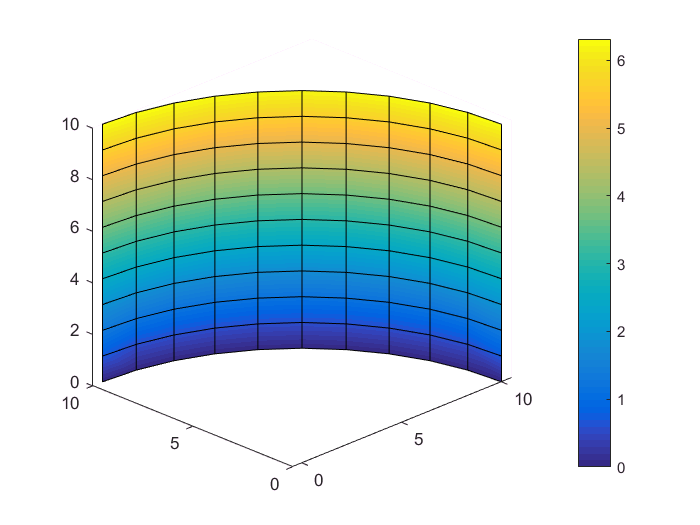

gauss_point=1/sqrt(3)*[-1 1];
[csi,eta]=meshgrid(gauss_point,gauss_point);
N1=@(a,b) 1/4*(1-a)*(1-b);
N2=@(a,b) 1/4*(1+a)*(1-b);
N3=@(a,b) 1/4*(1+a)*(1+b);
N4=@(a,b) 1/4*(1-a)*(1+b);
N1_a=@(a,b) -1/4*(1-b);
N1_b=@(a,b) -1/4*(1-a);
N2_a=@(a,b) 1/4*(1-b);
N2_b=@(a,b) -1/4*(1+a);
N3_a=@(a,b) 1/4*(1+b);
N3_b=@(a,b) 1/4*(1+a);
N4_a=@(a,b) -1/4*(1+b);
N4_b=@(a,b) 1/4*(1-a);
B=zeros(8,24,4);
% nodal locations
x1=COORD(ELEMENT(:,1),:);
x2=COORD(ELEMENT(:,2),:);
x3=COORD(ELEMENT(:,3),:);
x4=COORD(ELEMENT(:,4),:);
% element coordinate system
x0=1/4*(x1+x2+x3+x4);
xE=1/2*(x2+x3)-x0; xE=xE./repmat(sqrt(sum(xE.^2,2)),1,3);
zE=cross3(x2-x0,x3-x0); zE=zE./repmat(sqrt(sum(zE.^2,2)),1,3);
yE = cross3(zE,xE);yE=yE./repmat(sqrt(sum(yE.^2,2)),1,3);
% loop over element for stiffness matrix assembly
I=[];
J=[];
Kij=[];
Eid=[];
for k=1:size(x0,1)
    TEG = [xE(k,:)',yE(k,:)',zE(k,:)'].';
    % node positions in element coordinate system
    XE = TEG *([x1(k,:)',x2(k,:)',x3(k,:)',x4(k,:)']-[x0(k,:)',x0(k,:)',x0(k,:)',x0(k,:)']);
    obj.XE=XE;
    % nodal unit normals
    j1=@(xi,eta) .25*XE*[      -(1-eta),       (1-eta),       (1+eta),      -(1+eta)].';
    j2=@(xi,eta) .25*XE*[(1-xi)*-1     ,(1+xi)*-1     ,(1+xi)        ,(1-xi)        ].';
    obj.n1 = cross3(j1(-1,-1)',j2(-1,-1)'); obj.n1 = obj.n1./norm(obj.n1);
    obj.n2 = cross3(j1( 1,-1)',j2( 1,-1)'); obj.n2 = obj.n2./norm(obj.n2);
    obj.n3 = cross3(j1( 1, 1)',j2( 1, 1)'); obj.n3 = obj.n3./norm(obj.n3);
    obj.n4 = cross3(j1(-1, 1)',j2(-1, 1)'); obj.n4 = obj.n4./norm(obj.n4);
    obj.G= [t/(1-nu^2)*[1 nu 0;nu 1 0;0 0 (1-nu)/2]          ,zeros(3,3)                     , zeros(3,2) 
        zeros(3,3)  ,t^3/12/(1-nu^2)*[1 nu 0;nu 1 0;0 0 (1-nu)/2]  , zeros(3,2)
        zeros(2,3)  ,zeros(2,3)                     ,5/6*t/2/(1+nu)*eye(2)];
    %% Coordinate transformation at nodes
obj.A = zeros(3,3,4);
for n =1:4
    switch n
        case 1
            z_n = obj.n1;
        case 2
            z_n = obj.n2;
        case 3
            z_n = obj.n3;
        case 4
            z_n = obj.n4;
    end
    x_n = cross3([0 1 0],z_n)./norm(cross3([0 1 0],z_n));
    y_n = cross3(z_n,x_n);
    TNIE= [x_n;y_n;z_n];
    obj.A(1:3,1:3,n) = TNIE.'*[0 1 0; -1 0 0; 0 0 1]*TNIE;
end
XI = 1/sqrt(3)*[-1 -1; 1 1];
ETA = 1/sqrt(3)*[-1 1; -1 1];
ke=zeros(24);
for i = 1:2
    for j = 1:2
        xi = XI(i,j);
        eta = ETA(i,j);
        %% shape function evaluations
        Ni      = .25*[(1-xi)*(1-eta),(1+xi)*(1-eta),(1+xi)*(1+eta),(1-xi)*(1+eta)];
        dNdxii  = .25*[      -(1-eta),       (1-eta),       (1+eta),      -(1+eta)];
        dNdetai = .25*[(1-xi)*-1     ,(1+xi)*-1     ,(1+xi)        ,(1-xi)        ];
        
        %% Jacobian
        Jac = ...
            [ [dNdxii;
            dNdetai]* obj.XE.';
            Ni*[obj.n1',obj.n2',obj.n3',obj.n4'].' ];
        
        detJ = det(Jac);
        
        %% Rotation matrix
        z_i = cross3(Jac(1,:),Jac(2,:))./norm(cross3(Jac(1,:),Jac(2,:)));
        x_i = cross3([0 1 0],z_i)./norm(cross3([0 1 0],z_i));
        y_i = cross3(z_i,x_i);
        T = [x_i;y_i;z_i];
        
        %% Partial derivatives wrt physical coordinates
        dNdxzy = T/Jac*[dNdxii; dNdetai; 0 0 0 0];
        %% Element thickness at integration point
        tg = t;
        
        % Calculate strain displacement matrix at xi & eta
        
        e1=[dNdxzy(1,1)     0           0;
            0               dNdxzy(2,1) 0;
            dNdxzy(2,1)     dNdxzy(1,1) 0];
        
        e2=[dNdxzy(1,2)     0           0;
            0               dNdxzy(2,2) 0;
            dNdxzy(2,2)     dNdxzy(1,2) 0];
        
        e3=[dNdxzy(1,3)     0           0;
            0               dNdxzy(2,3) 0;
            dNdxzy(2,3)     dNdxzy(1,3) 0];
        
        e4=[dNdxzy(1,4)     0           0;
            0               dNdxzy(2,4) 0;
            dNdxzy(2,4)     dNdxzy(1,4) 0];
        
        s1=[0 0 dNdxzy(2,1) 0    Ni(1) 0
            0 0 dNdxzy(1,1) Ni(1) 0    0];
        s2=[0 0 dNdxzy(2,2) 0    Ni(2) 0
            0 0 dNdxzy(1,2) Ni(2) 0    0];
        s3=[0 0 dNdxzy(2,3) 0    Ni(3) 0
            0 0 dNdxzy(1,3) Ni(3) 0    0];
        s4=[0 0 dNdxzy(2,4) 0    Ni(4) 0
            0 0 dNdxzy(1,4) Ni(4) 0    0];
        
        z3 = zeros(3);
         B  = [[e1  z3
        z3  e1
        s1                  ] * [T z3; z3 T*obj.A(:,:,1)],...
        [e2  z3
        z3  e2
        s2                  ] * [T z3; z3 T*obj.A(:,:,2)],...
        [e3  z3
        z3  e3
        s3                  ] * [T z3; z3 T*obj.A(:,:,3)],...
        [e4  z3
        z3  e4
        s4                  ] * [T z3; z3 T*obj.A(:,:,4)]];
    %% Modify constitutive (stress-strain) matrix for bending
    G = obj.G;
    ke =ke+ B([1:2,4:5],:).'*G([1:2,4:5],[1:2,4:5])*B([1:2,4:5],:) *tg*detJ;
    end
end
 % 1 point integration for shear
 xi=0;
 eta=0;
  %% shape function evaluations
        Ni      = .25*[(1-xi)*(1-eta),(1+xi)*(1-eta),(1+xi)*(1+eta),(1-xi)*(1+eta)];
        dNdxii  = .25*[      -(1-eta),       (1-eta),       (1+eta),      -(1+eta)];
        dNdetai = .25*[(1-xi)*-1     ,(1+xi)*-1     ,(1+xi)        ,(1-xi)        ];
        
        %% Jacobian
        Jac = ...
            [ [dNdxii;
            dNdetai]* obj.XE.';
            Ni*[obj.n1',obj.n2',obj.n3',obj.n4'].' ];
        
        detJ = det(Jac);
        
        %% Rotation matrix
        z_i = cross3(Jac(1,:),Jac(2,:))./norm(cross3(Jac(1,:),Jac(2,:)));
        x_i = cross3([0 1 0],z_i)./norm(cross3([0 1 0],z_i));
        y_i = cross3(z_i,x_i);
        T = [x_i;y_i;z_i];
        
        %% Partial derivatives wrt physical coordinates
        dNdxzy = T/Jac*[dNdxii; dNdetai; 0 0 0 0];
        %% Element thickness at integration point
        tg = t;
        
        % Calculate strain displacement matrix at xi & eta
        
        e1=[dNdxzy(1,1)     0           0;
            0               dNdxzy(2,1) 0;
            dNdxzy(2,1)     dNdxzy(1,1) 0];
        
        e2=[dNdxzy(1,2)     0           0;
            0               dNdxzy(2,2) 0;
            dNdxzy(2,2)     dNdxzy(1,2) 0];
        
        e3=[dNdxzy(1,3)     0           0;
            0               dNdxzy(2,3) 0;
            dNdxzy(2,3)     dNdxzy(1,3) 0];
        
        e4=[dNdxzy(1,4)     0           0;
            0               dNdxzy(2,4) 0;
            dNdxzy(2,4)     dNdxzy(1,4) 0];
        
        s1=[0 0 dNdxzy(2,1) 0    Ni(1) 0
            0 0 dNdxzy(1,1) Ni(1) 0    0];
        s2=[0 0 dNdxzy(2,2) 0    Ni(2) 0
            0 0 dNdxzy(1,2) Ni(2) 0    0];
        s3=[0 0 dNdxzy(2,3) 0    Ni(3) 0
            0 0 dNdxzy(1,3) Ni(3) 0    0];
        s4=[0 0 dNdxzy(2,4) 0    Ni(4) 0
            0 0 dNdxzy(1,4) Ni(4) 0    0];
        
        z3 = zeros(3);
         B  = [[e1  z3
        z3  e1
        s1                  ] * [T z3; z3 T*obj.A(:,:,1)],...
        [e2  z3
        z3  e2
        s2                  ] * [T z3; z3 T*obj.A(:,:,2)],...
        [e3  z3
        z3  e3
        s3                  ] * [T z3; z3 T*obj.A(:,:,3)],...
        [e4  z3
        z3  e4
        s4                  ] * [T z3; z3 T*obj.A(:,:,4)]];
    %% Modify constitutive (stress-strain) matrix for bending
    G = obj.G;
    ks = B([3,6:8]  ,:).'*G([3,6:8]  ,[3,6:8]  )*B([3,6:8]  ,:) *tg*detJ;
    ke = ke + 4*ks;
    %% transform to global coordinate system and save
    REG(22:24,22:24)=TEG;REG(19:21,19:21)=TEG;REG(16:18,16:18)=TEG;REG(13:15,13:15)=TEG;
    REG(10:12,10:12)=TEG;REG(7:9,7:9)=TEG;REG(4:6,4:6)=TEG;REG(1:3,1:3)=TEG;
    RGE = REG.';
    % save the I,J,K for assembly
    [ie,je,kke]=find(RGE*ke*REG);
    eid=k*ones(size(ie));
    I=[I;ELEMENT_DOF(k,ie)'];
    J=[J;ELEMENT_DOF(k,je)'];
    Kij=[Kij;kke];
    Eid=[Eid;eid];
end

clamped_nodes=find(COORD(:,3)==0);
clamped_DOF=[6*(clamped_nodes-1)+1;6*(clamped_nodes-1)+2;6*(clamped_nodes-1)+3;6*(clamped_nodes-1)+4;6*(clamped_nodes-1)+5;6*(clamped_nodes-1)+6];
load_nodes=find(COORD(:,3)==10);
extr_load_nodes=find(COORD(:,3)==10&(COORD(:,2)==10|COORD(:,1)==10));
extr_load_dof=[6*(extr_load_nodes-1)+3];
load_DOF=[6*(load_nodes-1)+3];
all_DOFs=(1:6*size(COORD,1))';
free_DOFs=setdiff(all_DOFs,clamped_DOF);
load_module=[ones(size(load_DOF));-0.5*[1;1]];
F=sparse([load_DOF;extr_load_dof],1,load_module,6*size(COORD,1),1);
K=sparse(I,J,E*Kij,6*size(COORD,1),6*size(COORD,1));
K=(K+K')/2;
U=zeros(size(F));
U(free_DOFs)=K(free_DOFs,free_DOFs)\F(free_DOFs);

figure
patch('Faces',ELEMENT,'Vertices',COORD,'FaceVertexCData',U(3:6:end),'FaceColor','interp');
colorbar
axis equal
view(-45,24)

function p = cross3(u,v)
    p = [u(:,2).*v(:,3) u(:,3).*v(:,1) u(:,1).*v(:,2)]-[u(:,3).*v(:,2) u(:,1).*v(:,3) u(:,2).*v(:,1)];
end